# Expand Example 2.15:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RLC circuit shown in the figure. Let element values be $R=2\Omega$, $L=1$ H, and $C=1/26$ F.

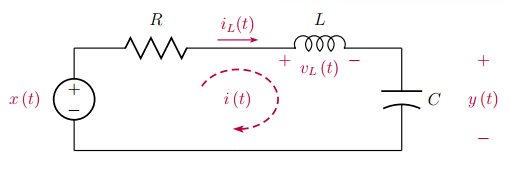 

The characteristic equation was found in Example 2.15 to be 

        
$$s^{2}+2s+26=0$$


The homogeneous solution is in the form

        
$$y_{h}(t)=d_{1}\,e^{-t}\,\cos(5t)+d_{2}\,e^{-t}\,\sin(5t)$$


Experiment by changing capacitor voltage amd inductor current at time $t=0$.

y0 = 2; % Initial capacitor voltage
i0 = 0.5; % Initial inductor current

Imposing the initial conditions yields

        $d_{1}=y_{0}$   and   $-d_{1}+5d_{2}=\frac{i_{0}}{C}$

Determine and graph the natural response $y_{h}(t)$.

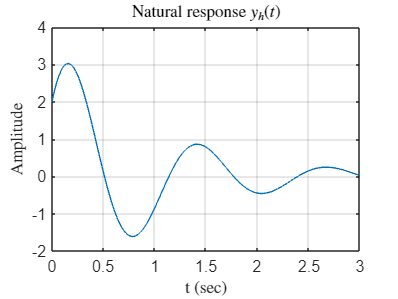

d1 = y0;
d2 = (26*i0+d1)/5;  % Solve the eqns for d1 and d2
t = [0:0.01:3];     % Vector of time instants
yh = d1*exp(-t).*cos(5*t)+d2*exp(-t).*sin(5*t);  % Natural response
plot(t,yh); grid;
axis([0,3,-2,4]);
set(0,'defaultTextInterpreter','latex')
title('Natural response $y_{h}(t)$');
xlabel('t (sec)'); 
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex')